# Mapping your surroundings using an Arduino and an ultrasonic sensor

This is a updated MATLAB script shows how to use MATLAB to map your surroundings using an Arduino and an ultrasonic sensor.

[https://www.mathworks.com/matlabcentral/fileexchange/58434-mapping-your-surroundings-using-matlab-and-arduino](https://www.mathworks.com/matlabcentral/fileexchange/58434-mapping-your-surroundings-using-matlab-and-arduino)

Copyright 2016 The MathWorks, Inc

Updated by:

          Alberto Y. Shimahara

          Jan/2020

          OpenCadd Advanced Tecnology (MW Representative in Brazil)

## Create an Arduino object with the necessary add-ons.

We update this demo, because the ultrasonic sensor is already included in MATLAB R2019x, dont requires a 3rd library.

a = arduino('COM3','UNO','Libraries',{'Ultrasonic','Servo'})

a =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'Servo', 'Ultrasonic'}


## Create an ultrasonic sensor object with trigger pin D12 and echo pin D13.

`%ultrasonicObj` `= ultrasonic(`[`arduinoObj`](https://localhost:31515/static/help/supportpkg/arduinoio/ref/arduinoio.ultrasonic.html#mw_43938086-e8e1-4c38-94ba-07f24581559c)`,`[`triggerPin`](https://localhost:31515/static/help/supportpkg/arduinoio/ref/arduinoio.ultrasonic.html#mw_570ba799-339d-46cc-a010-df0d5e77ff3a)`,`[`echoPin`](https://localhost:31515/static/help/supportpkg/arduinoio/ref/arduinoio.ultrasonic.html#mw_ccdbc70f-78f5-4ffc-85f5-6078b1ed4571)`)`

sensor = ultrasonic(a,'D11', 'D12')

sensor =   Ultrasonic with properties:

    TriggerPin: 'D11'
       EchoPin: 'D12'


## Create a servo object for the servo connected to pin D3. 

servo_motor = servo(a, 'D3')

servo_motor =   Servo with properties:

                 Pin: 'D3'
    MinPulseDuration: 5.44e-04 (seconds)
    MaxPulseDuration: 2.40e-03 (seconds)


## Rotate the servo motor from 0 to 180 degrees.

Every time the motor rotates, determine the distance of any obstacles via the bounceback time of the ultrasonic ping. 

Take two measurements and average them for accuracy. Record the angle and the distance (in cm)

Obs: In comparison with the base demo, we changed the variable name "table" to "tableValues", to avoid conflicts because table is a data type in MATLAB.

i = 1;
tableValues = zeros(180,2);
for theta = 0 : 1/180 : 1
    writePosition(servo_motor, theta);
    dist1 = readDistance(sensor)*170;
    pause(.04);
    dist2 = readDistance(sensor)*170;
    dist = (dist1+dist2)/2;
    tableValues(i,1) = (i-1);
    tableValues(i,2) = round(dist * 100,2);
    i = i + 1;
end
%  Rotate the servo motor from 180 to 0 degrees. Replace the values in the
%  table with the average of the clockwise and counterclockwise scans to
%  improve the accuracy of the map.
j = 1; 
for theta = 1 : -1/180 : 0
    writePosition(servo_motor, theta);
    dist1 = readDistance(sensor)*170;
    pause(.04);
    dist2 = readDistance(sensor)*170;
    dist = (dist1+dist2)/2;
    tableValues(i-j,2) = (tableValues(i-j,2) + round(dist * 100,2))/2;
    j = j + 1;
end

## Make a polar plot of the distance data to display the map.

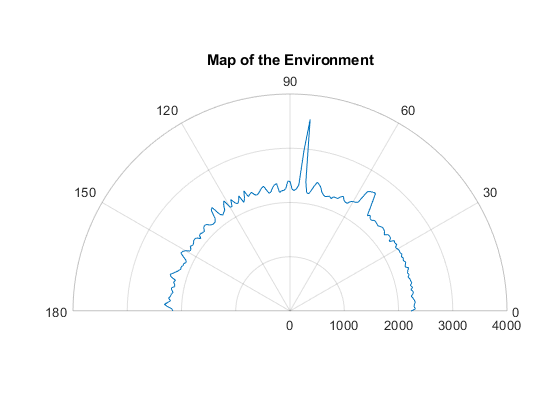

polarplot (tableValues(:,1)*pi/180, tableValues (:,2));
title('Map of the Environment');
thetalim([0 180]);
grid on;